# 函数定义

function mni_coord = xyz2mni(affine, vox_coord)
    homo_coord = [vox_coord(:); 1];
    mni_coord = affine * homo_coord;
    mni_coord = mni_coord(1:3)';
end

function vox_coord = mni2xyz(affine, mni_coord)
    homo_coord = [mni_coord(:); 1];
    vox_coord = affine \ homo_coord;
    vox_coord = vox_coord(1:3)';
end

# 读取并显示BOLD数据和T1数据

BOLD像（bold_y.nii.gz）；T1结构像（t1_y.nii.gz）

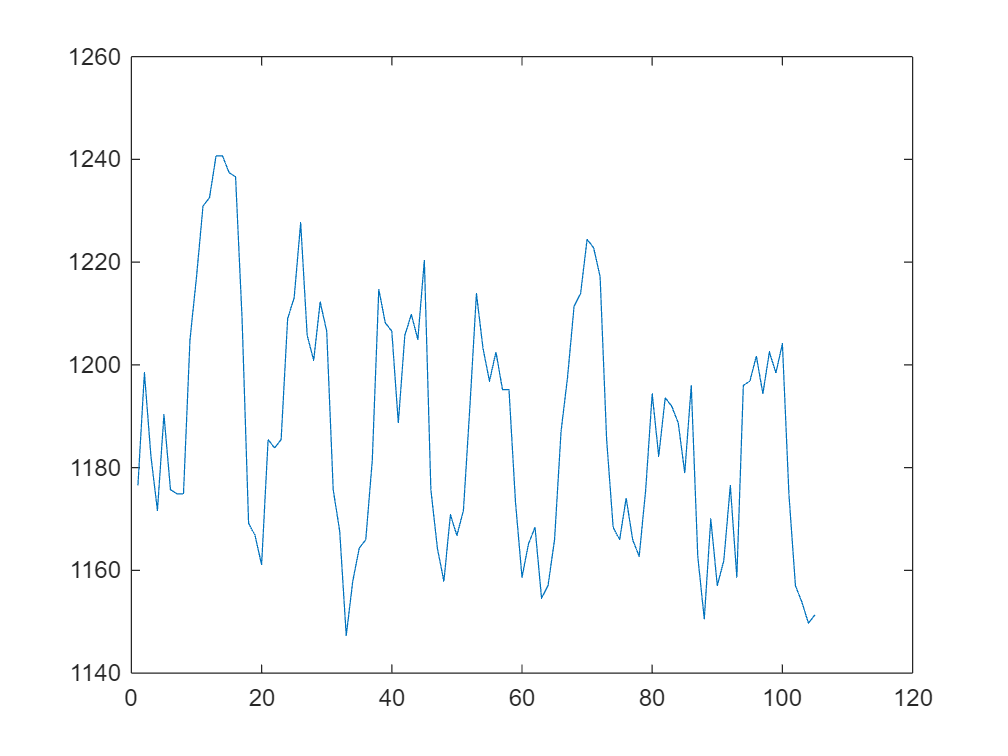

my_fmri = load_nii('bold_y.nii.gz'); % BOLD images stored in NIFTI file bold_y.nii.gz
B = squeeze(my_fmri.img(60,27,23,:)); % The BOLD signal at voxel [60,27,23] now stored as vector B
figure;
plot(B); % plot the BOLD signal at voxel [60,27,23]

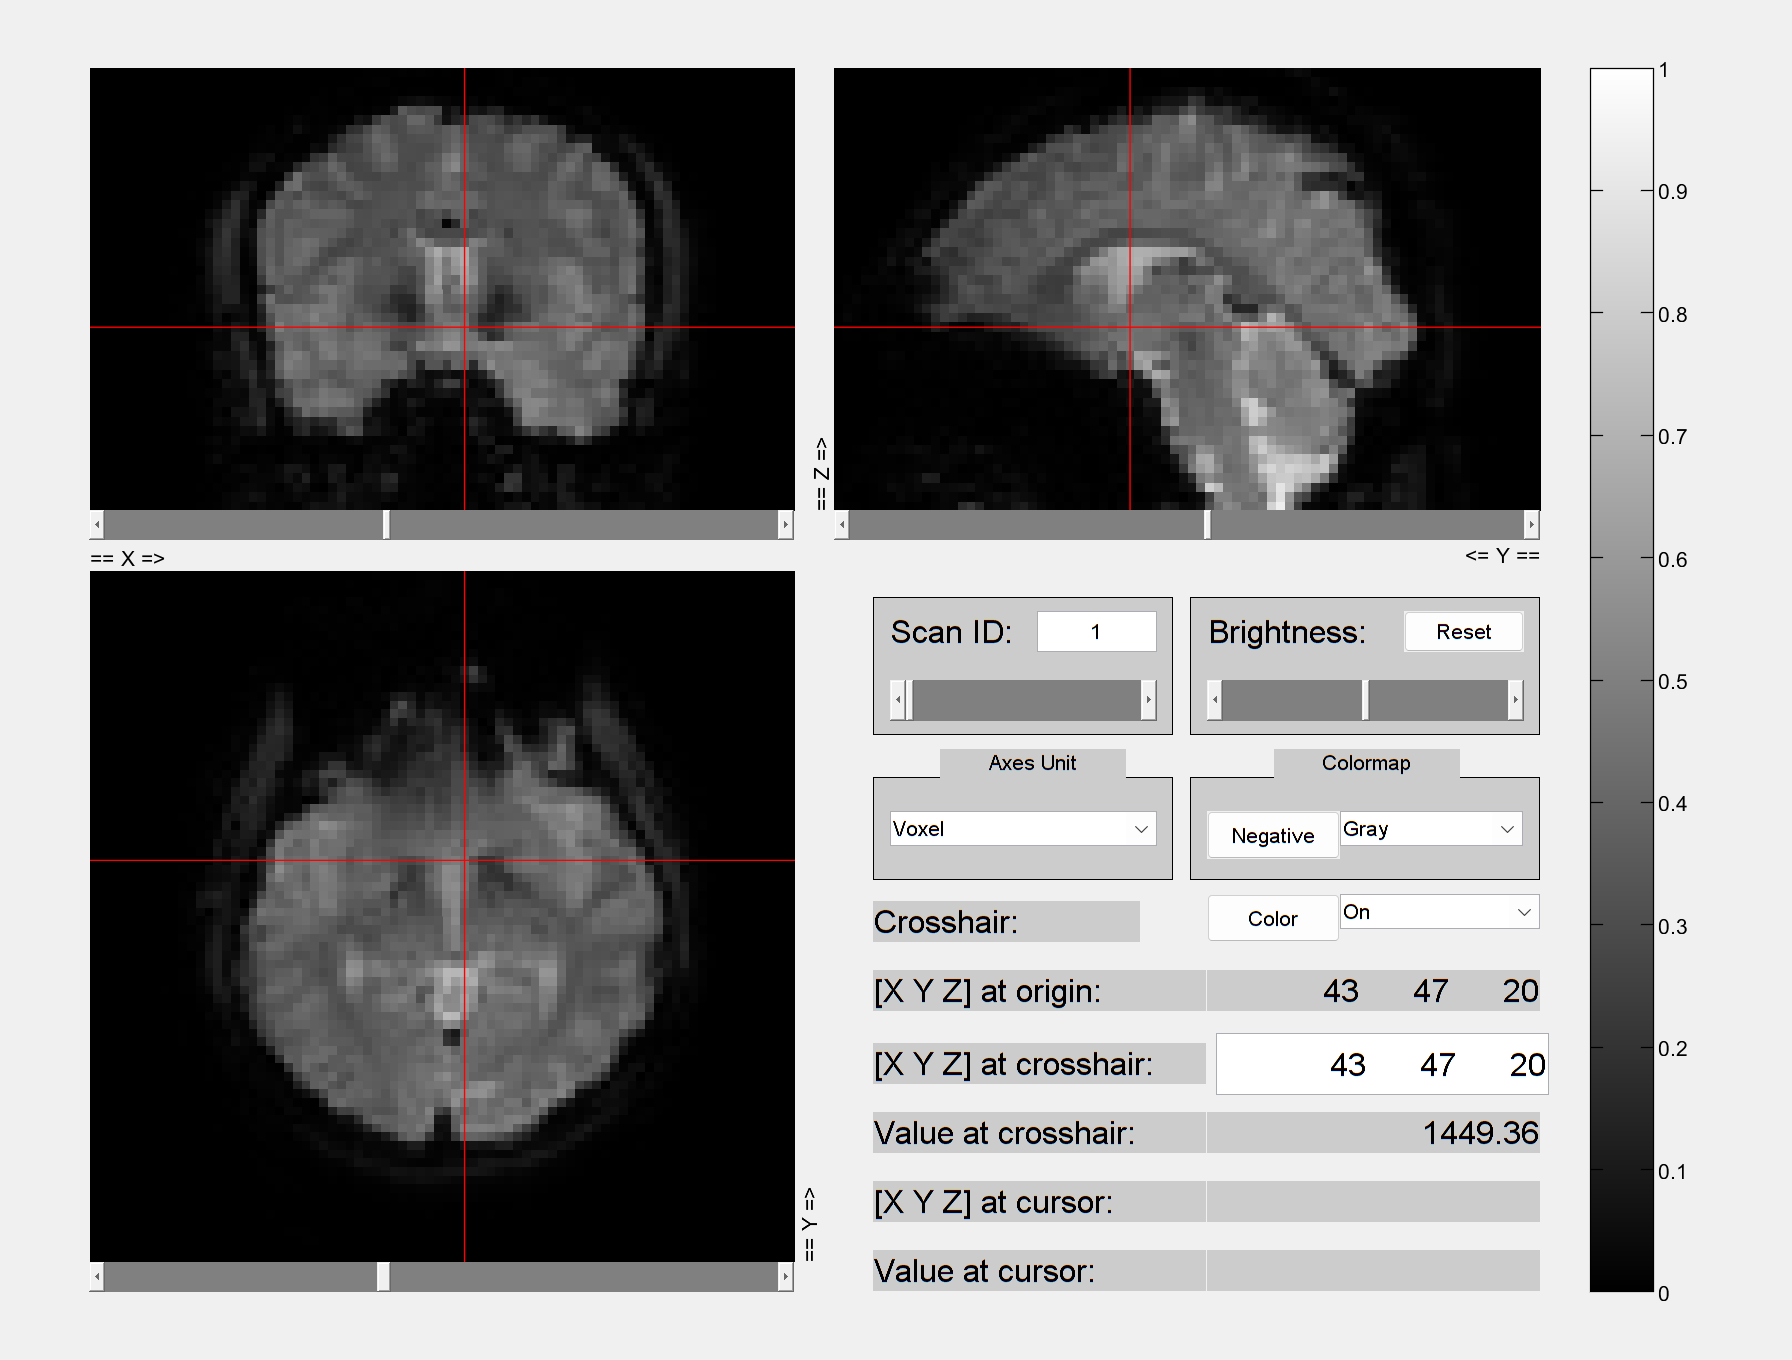

view_nii(my_fmri); % You can explore all voxels in the 4-D data containing 105 volumes

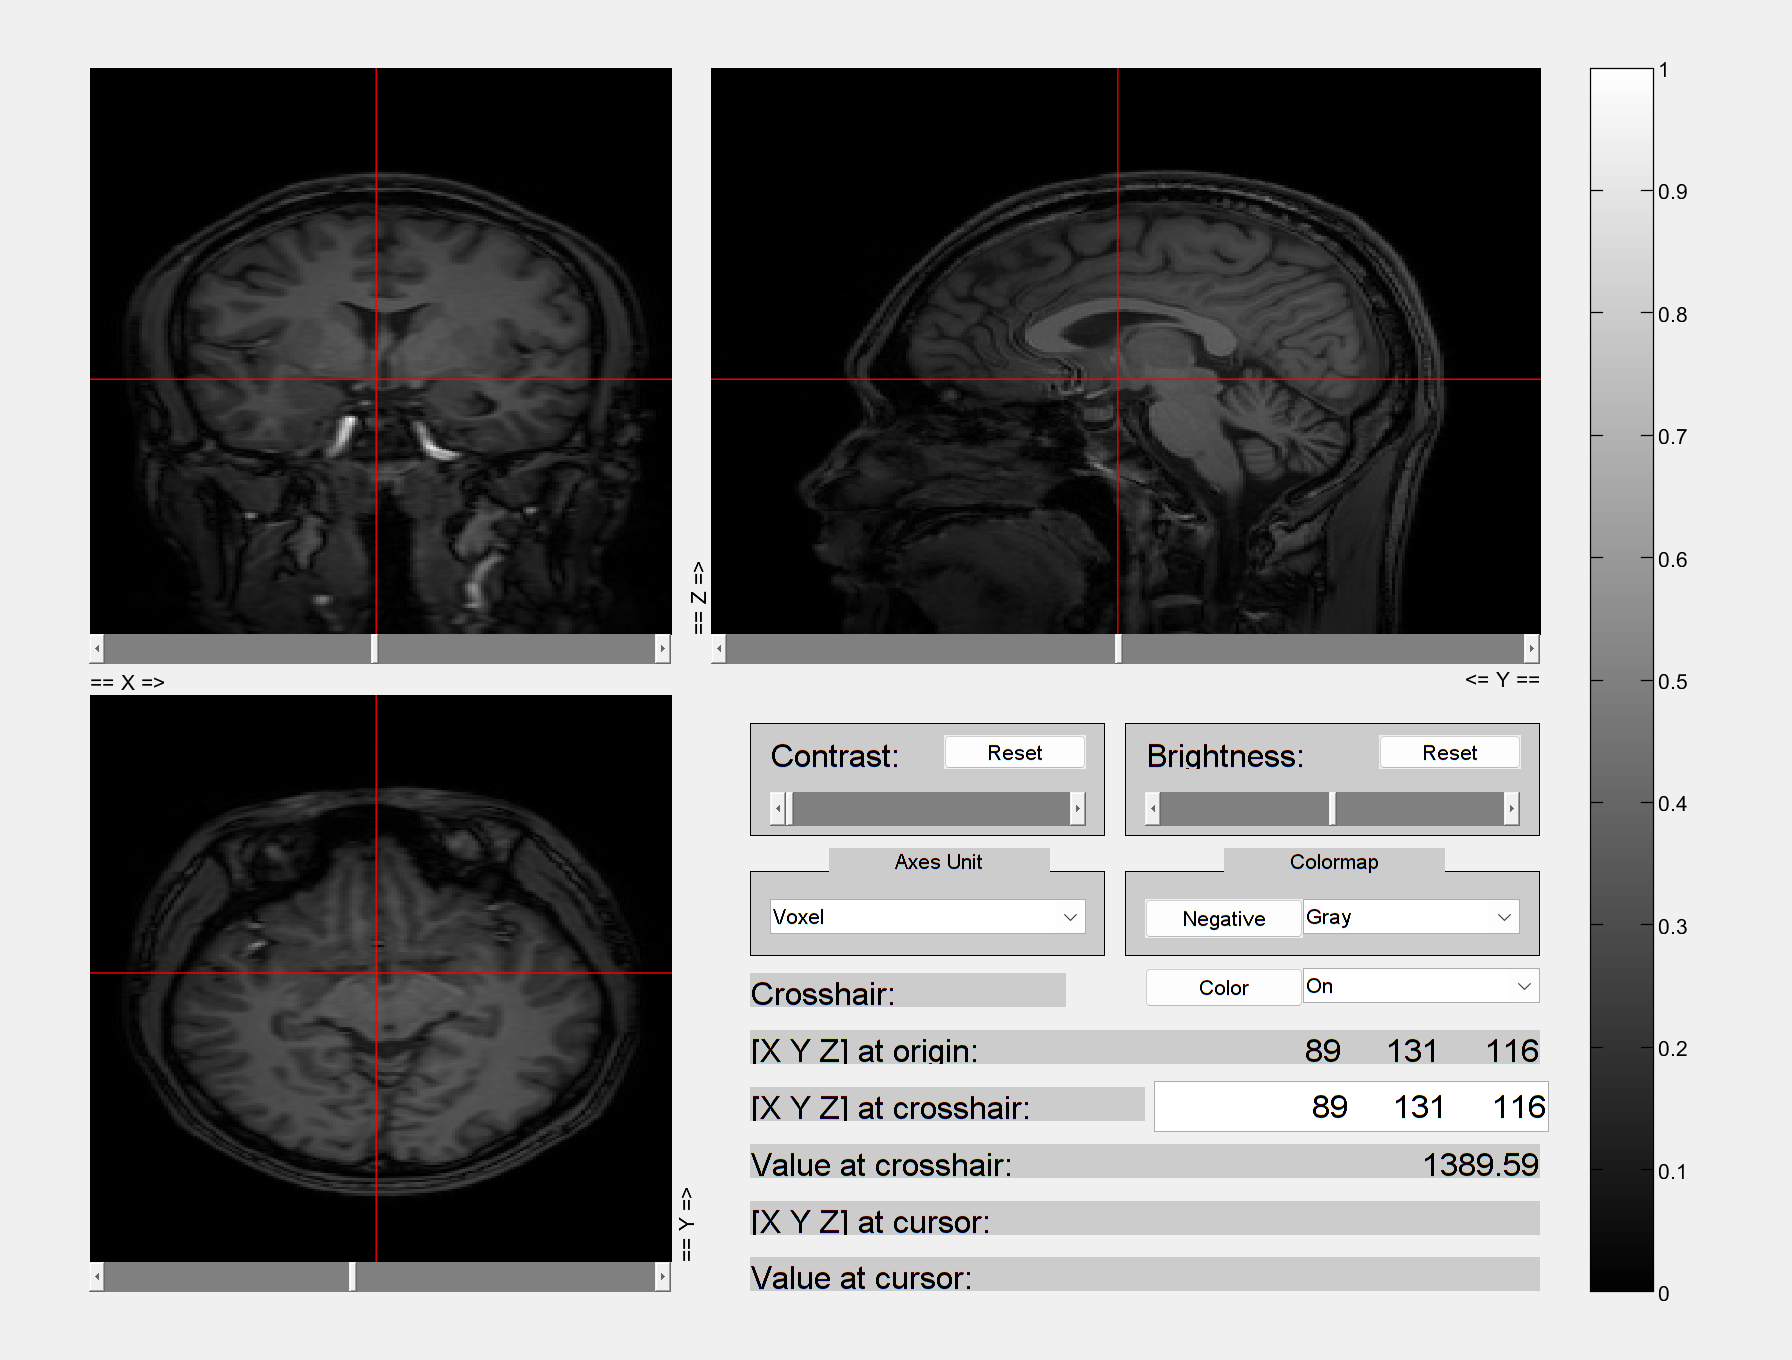


t1_fmri = load_nii('t1_y.nii.gz');
view_nii(t1_fmri);

# 测试坐标变换

affine_bold = my_fmri.hdr.hist.new_affine; % 使用sform矩阵
affine_t1 = t1_fmri.hdr.hist.new_affine;

% convert BOLD XYZ coordinates to MNI space
v_mni = xyz2mni(affine_bold, [60, 27, 23])

v_mni =   -61.7719  -53.5288   11.7070


% convert MNI space to T1 XYZ coordinates
v_t1 = mni2xyz(affine_t1, v_mni)

v_t1 =   179.0820  126.2780   26.1350


% convert MNI space back to BOLD XYZ coordinates
v_bold = mni2xyz(affine_bold, v_mni)

v_bold =     60    27    23


# t检验功能区定位

给出对视觉运动刺激有显著激活的前20个voxels，给出它们的MNI坐标。

总时间点：注视 7 + 14*7（刺激和基线各7次，每次7个TR）=7+98=105。这样时间点的分组是：前7个TR是注视，然后是刺激和基线交替，每个block7个TR，共7次刺激和7次基线。

对于每个体素，提取在刺激时间点的信号和基线时间点的信号，进行双样本t检验，得到p值，然后根据p值排序，选择前20个体素。可能会有多个比较的问题，需要进行多重比较校正？

[X, Y, Z, T] = size(my_fmri.img);

% 定义刺激和基线块（7对配对条件）
stim_blocks = {8:14, 22:28, 36:42, 50:56, 64:70, 78:84, 92:98};   % 7个刺激块TR索引
base_blocks = {15:21, 29:35, 43:49, 57:63, 71:77, 85:91, 99:105}; % 对应的7个基线块

% 将4D数据转换为2D矩阵（体素×时间点）
data_2d = reshape(my_fmri.img, [X*Y*Z, T]);

% 初始化p值存储
p_values = zeros(X*Y*Z, 1);

% 对每个体素进行配对t检验
for i = 1:X*Y*Z
    stim_means = zeros(7,1);
    base_means = zeros(7,1);
    
    % 计算每个block的平均信号
    for blk = 1:7
        stim_TRs = stim_blocks{blk};
        base_TRs = base_blocks{blk};
        stim_means(blk) = mean(data_2d(i, stim_TRs));
        base_means(blk) = mean(data_2d(i, base_TRs));
    end
    
    % 配对t检验（比较刺激vs基线的7对平均信号）
    [~, p_values(i)] = ttest(stim_means, base_means);
end

% 多重比较校正
valid_mask = ~isnan(p_values);
p_fdr = mafdr(p_values(valid_mask), 'BHFDR', true);
p_values(valid_mask) = p_fdr;

% 处理无效值并排序
valid_p = p_values(~isnan(p_values));
[sorted_p, idx] = sort(valid_p);
top20_idx = idx(1:20);

% 转换前20个体素坐标
mni_coords = zeros(20, 3);
for i = 1:20
    vox_coord = top20_voxels(i,:);
    mni_coords(i,:) = xyz2mni(affine_bold, vox_coord);
end

# 查看结果

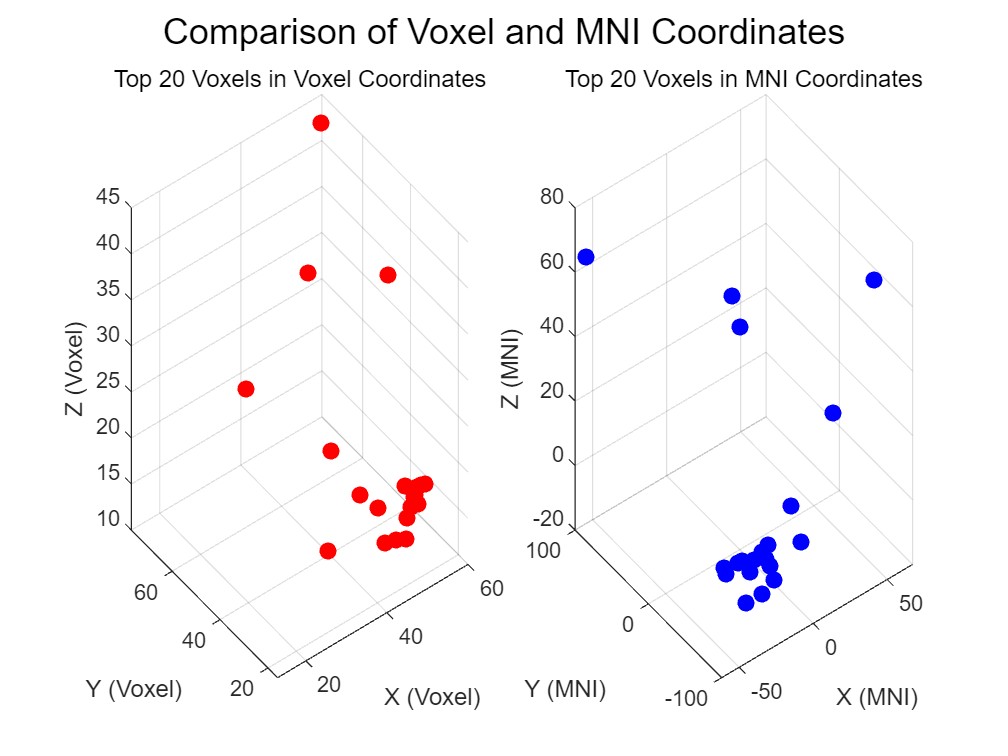

figure;

% 1. 绘制体素坐标的 3D 点图
subplot(1, 2, 1); % 创建子图（左侧）
scatter3(top20_voxels(:,1), top20_voxels(:,2), top20_voxels(:,3), ...
         50, 'r', 'filled'); % 红色点，大小为50
xlabel('X (Voxel)');
ylabel('Y (Voxel)');
zlabel('Z (Voxel)');
title('Top 20 Voxels in Voxel Coordinates');
grid on;
view(3); % 设置视角为3D视图

% 2. 绘制 MNI 坐标的 3D 点图
subplot(1, 2, 2); % 创建子图（右侧）
scatter3(mni_coords(:,1), mni_coords(:,2), mni_coords(:,3), ...
         50, 'b', 'filled'); % 蓝色点，大小为50
xlabel('X (MNI)');
ylabel('Y (MNI)');
zlabel('Z (MNI)');
title('Top 20 Voxels in MNI Coordinates');
grid on;
view(3); % 设置视角为3D视图

% 调整布局
sgtitle('Comparison of Voxel and MNI Coordinates');


disp(mni_coords);

  -61.7719   83.8114   68.6139
  -12.3883  -72.7564   -9.2587
   15.0470  -53.5288   -9.2587
  -37.0801  -53.5288   -3.2685
  -20.6189  -83.7436   -0.2734
  -23.3624  -83.7436    2.7217
  -28.8495  -78.2500    2.7217
  -34.3366  -72.7564    2.7217
  -37.0801  -72.7564    2.7217
  -26.1060  -83.7436    5.7168
    1.3293  -67.2628    8.7119
   26.0211  -75.5032   32.6727
   67.1741  -48.0352   56.6335
   -4.1577    1.4073   59.6286
  -26.1060  -53.5288   68.6139
  -26.1060  -61.7692  -15.2489
  -23.3624  -78.2500   -9.2587
  -31.5930  -78.2500   -0.2734
  -42.5672  -67.2628   -0.2734
  -12.3883  -64.5160   -0.2734



# 将voxels绘制在T1结构像上

找出voxels的空间位置，画在T1结构像（t1_y.nii.gz）相应的脑片slice上（可能不止在一个slice）。注意BOLD像和T1结构像的XYZ坐标定义不同，需要进行坐标变换。首先要统一转换为标准的MNI坐标

t1_vol = t1_fmri.img; % 3D T1 volume

t1_coords = zeros(20, 3);
for i = 1:20
    t1_coords(i,:) = round(mni2xyz(affine_t1, mni_coords(i,:)));
end

disp(t1_coords);

    42   183    26
   198   105    76
   179   105   103
   179   111    51
   209   114    67
   209   117    65
   204   117    59
   198   117    54
   198   117    51
   209   120    62
   193   123    89
   201   147   114
   174   171   155
   124   174    84
   179   183    62
   187    99    62
   204   105    65
   204   114    56
   193   114    45
   190   114    76




t1_coords(:, [1 3]) = t1_coords(:, [3 1]);

% 获取T1图像尺寸
[x_size, y_size, z_size] = size(t1_vol)

x_size = 180

y_size = 256

z_size = 256


% 过滤有效坐标
valid_mask = (t1_coords(:,1) >= 1) & (t1_coords(:,1) <= x_size) & ...
             (t1_coords(:,2) >= 1) & (t1_coords(:,2) <= y_size) & ...
             (t1_coords(:,3) >= 1) & (t1_coords(:,3) <= z_size);
valid_voxels = t1_coords(valid_mask, :);

disp(valid_voxels);

    26   183    42
    76   105   198
   103   105   179
    51   111   179
    67   114   209
    65   117   209
    59   117   204
    54   117   198
    51   117   198
    62   120   209
    89   123   193
   114   147   201
   155   171   174
    84   174   124
    62   183   179
    62    99   187
    65   105   204
    56   114   204
    45   114   193
    76   114   190



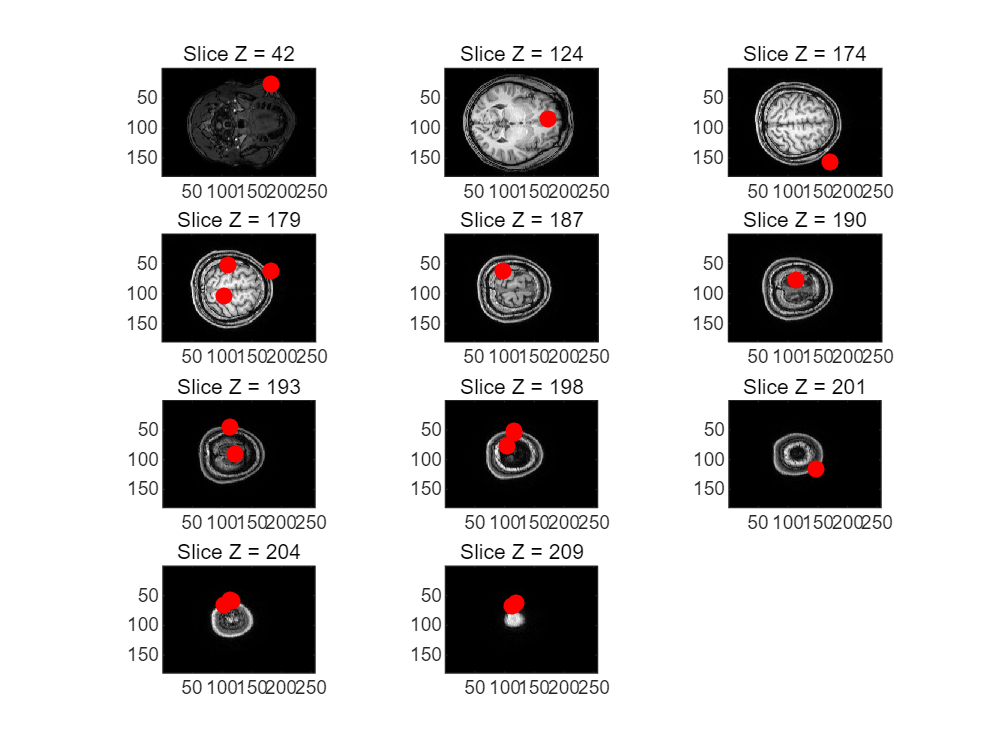


selected_slices = unique(valid_voxels(:,3));

% 可视化
figure;
colormap gray;
for s = 1:length(selected_slices)
    z = selected_slices(s);
    idx = find(valid_voxels(:,3) == z);
    if isempty(idx), continue; end
    
    % 调整切片方向
    t1_slice = t1_vol(:,:,z);
    
    subplot(ceil(length(selected_slices)/3), 3, s);
    imagesc(t1_slice);
    axis equal image;
    title(sprintf('Slice Z = %d', z));
    hold on;
    
    % 绘制激活点
    for i = 1:length(idx)
        % 调整坐标方向
        x = valid_voxels(idx(i), 1);
        y = valid_voxels(idx(i), 2);
        
        % 绘制
        scatter(y, x, 50, 'r', 'filled');
    end
    hold off;
end